# Cvičení 6 - B2M31AEDA

## Nahrání dat

**Důležité! **V dnešním cvičení naleznete na Moodle ke stažení dva data sety, `data.csv` a `large_dataset.csv`. Předtím, než přistoupíte k načítání dat do Matlabu (klasicky pomocí funkce `readtable`, viz předešlá cvičení), musíte se rozhodnout, který z těchto dvou datasetu použijete.

## ČTĚTE POZORNĚ ZADÁNÍ!!! 😊

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week06' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
small_dataset = readtable('data.csv','ReadVariableNames',true);
large_dataset = readtable('large_dataset.csv','ReadVariableNames',true);

HC = struct( ...
    'DDKR', small_dataset.DDKR(ismember(small_dataset.group, 'HC')), ...
    'jitter', large_dataset.jitter(ismember(large_dataset.group, 'HC')));
HC.DDKR_mean = mean(HC.DDKR);
HC.jitter_mean = mean(HC.jitter);
HC.DDKR_std = std(HC.DDKR);
HC.jitter_std = std(HC.jitter);

EP = struct( ...
    'DDKR', small_dataset.DDKR(ismember(small_dataset.group, 'EP')), ...
    'jitter', large_dataset.jitter(ismember(large_dataset.group, 'EP')), ...
    'speech_small', small_dataset.Speech(ismember(small_dataset.group, 'EP')), ...
    'speech_large', large_dataset.Speech(ismember(large_dataset.group, 'EP')));
EP.DDKR_mean = mean(EP.DDKR);
EP.jitter_mean = mean(EP.jitter);
EP.DDKR_std = std(EP.DDKR);
EP.jitter_std = std(EP.jitter);

## 1. Estimace potřebné velikosti vzorku

V této části potřebujete program GPower, volně ke stažení pomocí odkazu v zadání. V zadání se také nachází na konci PDF návod na použití.

Pečlivě čtěte zadání, v této části je možné udělat mnoho malých chyb.

- Nejprve si musíte přečíst otázky na konci zadání (v 3. části), na které budete chtít odpovídat.

- Vyberte statistický test, který na jejich zodpovězení použijete. Správně vyhodnoťte normalitu parametrů (viz zadání).

- Vypočítejte pomocí GPower potřebnou velikost vzorku.

**Otázky:**

- Zapište jaké testy použijete pro zodpovězení otázek z části 3.

- Zapište vypočtené minimální potřebné velikosti vzorku pro jednotlivé testy.

- Zaznamenejte jaké datasety jste se rozhodli použít případně jaké parametry jste se rozhodli vyřadit.

#### Vaše odpovědi a výsledky:

**Minimální potřebná velikost vzorku:**

- DDKG: 436

- DDKR: 20

- stdF0: 384

- jitter: 54

**Výběr datasetů:**

- Použité: DDKR (menší dataset), jitter (větší dataset)

- Vyřazené pro nedostatek dat: DDKG, stdF0

**Použité testy:**

Pro spávný výběr testů je neprve nutné provést test normality vstupních dat - zvolen Shapirův-Wilkův:

alpha = 0.05;

for sample = ["HC.DDKR", "EP.DDKR", "HC.jitter", "EP.jitter"]
    [H, p, SWstatistic] = swtest(eval(sample));

    if p < 0.001
        pReport = "p < 0.001";
    elseif p < 0.01
        pReport = sprintf('p = %.3f', p);
    else
        pReport = sprintf('p = %.2f', p);
    end

    if H == 0
        fprintf(['\tShapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption\n' ...
            'regarding the population distribution of a random sample %s (M = %.2f, SD = %.2f) at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, eval(sprintf('%s_mean', sample)), eval(sprintf('%s_std', sample)), alpha, length(eval(sample))-1, SWstatistic, pReport)
    else
        fprintf(['\tShapiro-Wilk test rejects the null hypothesis of composite normality regarding the population\n' ...
            'distribution of a random sample %s (M = %.2f, SD = %.2f) at significance level α = %.2f,\n' ...
            'W(%d) = %.4f, %s.\n\n'], ...
            sample, eval(sprintf('%s_mean', sample)), eval(sprintf('%s_std', sample)), alpha, length(eval(sample))-1, SWstatistic, pReport)
    end
end

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample HC.DDKR (M = 7.09, SD = 0.76) at significance level α = 0.05,
W(12) = 0.9289, p = 0.33.

	Shapiro-Wilk test confirms that the null hypothesis of composite normality is a reasonable assumption
regarding the population distribution of a random sample EP.DDKR (M = 5.17, SD = 1.62) at significance level α = 0.05,
W(12) = 0.9240, p = 0.28.



	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample HC.jitter (M = 0.83, SD = 0.73) at significance level α = 0.05,
W(24) = 0.7058, p < 0.001.

	Shapiro-Wilk test rejects the null hypothesis of composite normality regarding the population
distribution of a random sample EP.jitter (M = 1.68, SD = 1.52) at significance level α = 0.05,
W(27) = 0.8087, p < 0.001.



- t-test jakožto parametrický test rozdílů mezi skupinami pro data *DDKR*

- Mann-Whitney U test jakožto neparametrický test rozdílů mezi skupinami pro data *jitter*

- Pearsonova korelace jakožto parametrický test korelace pro data *DDKR*

- Spearmanova korelace jakožto neparametrický test korelace pro data *jitter*

## 2. Vizualizace vybraných dat

Skupiny dat vybrané pro zodpovězení otázek z části 3 vhodně vizualizujte. Použijte zobrazení, na kterém bude nejvíce zřetelný efekt mezi skupinami.

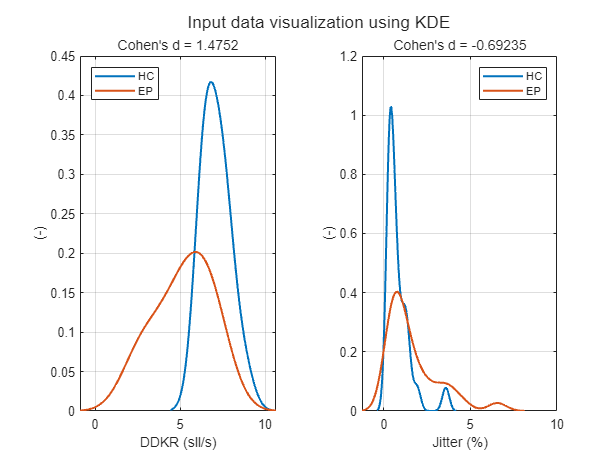

figure(1)
tiles = tiledlayout(1,2);

nexttile
[f, xf] = kde(HC.DDKR);
plot(xf, f, LineWidth=1.5)
hold on
[f, xf] = kde(EP.DDKR);
plot(xf, f, LineWidth=1.5)
hold off
grid on
legend('HC', 'EP', 'Location', 'northwest')
xlabel('DDKR (sll/s)')
ylabel('(-)')
subtitle(['Cohen''s d = ' num2str(meanEffectSize(HC.DDKR, EP.DDKR, 'Effect', 'cohen').Effect)])

nexttile
[f, xf] = kde(HC.jitter);
plot(xf, f, LineWidth=1.5)
hold on
[f, xf] = kde(EP.jitter);
plot(xf, f, LineWidth=1.5)
hold off
grid on
legend('HC', 'EP', 'Location', 'northeast')
xlabel('Jitter (%)')
ylabel('(-)')
subtitle(['Cohen''s d = ' num2str(meanEffectSize(HC.jitter, EP.jitter, 'Effect', 'cohen').Effect)])

title(tiles, 'Input data visualization using KDE')

- Slovně zhodnoťte (vizuálním odhadem), zdali je mezi skupinami vidět nějaký efekt skupin (size effect).

- Vypočítejte velikost efektu skupin pomocí Cohenova d a podle jeho velikosti uveďte, jak velký tento efekt je.

#### Vaše odpovědi a výsledky:

- Mezi skupinami pozorujeme vizuálním odhadem silný efekt pro oba parametry.

- Výpočet velikosti efektu pomocí Cohenova d (pomocí funkce *meanEffectSize *s parametrem *Effect=cohen*) pozorování potvrzuje.

## 3. Úloha

K následujícím otázkám navrhněte hypotézy, vyberte vhodné testy, nastavte hladinu statistické významnosti korigovanou pro ošetření chyby I. typu a korektně reportujte svoje výsledky do Moodle. **Mějte na paměti, že oproti předešlým cvičením, zde budete mít jednu hypotézu na každou z otázek, a pod touto hypotézou provedete určitý počet testů. **

- *Vykazuje skupina EP rozdíly oproti skupině zdravých lidí z pohledu nějakého z příznaků DDKG, DDKR, stdF0 nebo jitter?*

Lze potvrdit na hladině statistické významnosti $\alpha =0\ldotp 05$, že skupina EP vykazuje rozdíly oproti skupině zdravých lidí z pohledu obou zkoumaných příznaků *DDKR *a *jitter*.

- *Odráží příznak DDKG, DDKR, stdF0 nebo jitter motorické zhodnocení pomocí skóre NNIPPS? Vyberte si ***jednu položku*** z dotazníku NNIPPS, pro kterou vztah vyšetříte.*

Lze potvrdit na hladině statistické významnosti $\alpha =0\ldotp 05$, že oba zkoumané přiznaky *DDKR *a *jitter *odráží motorické zhodnocení NNIPPS (vybraná položka *speech*). Dosažená síla testů je uvedena pro jednotlivé testy níže.

### Hypotézy, reporty:

#### Rozdíly mezi HC a EP z pohledu parametru *DDKR*

- Zvolený test: T-test (parametrická data)

- H0: Zkoumané skupiny vstupních dat pochází z populací se stejnou střední hodnotou.

- H1: Zkoumané skupiny vstupních dat pochází z populací s různými středními hodnotami.

- Hladina významnosti (Bonferroniho korekce): $\alpha =0\ldotp 05/2=0\ldotp 025$.

alpha = 0.025;

[~, p, ~, stats] = ttest2(HC.DDKR, EP.DDKR, "Alpha", alpha);
assert(p < 0.001)
fprintf(['The healthy subjects (M = %.2f, SD = %.2f) compared to the subjects exhibiting signs of Parkinsonism\n' ...
    'due to the use of ephedrone (M = %.2f, SD = %.2f) demonstrated significantly higher values of DDKR,\n' ...
    't(%d) = %.2f, p < 0.001, indicating better motor control of vocal cords.'], ...
    HC.DDKR_mean, HC.DDKR_std, EP.DDKR_mean, EP.DDKR_std, stats.df, stats.tstat)

The healthy subjects (M = 7.09, SD = 0.76) compared to the subjects exhibiting signs of Parkinsonism
due to the use of ephedrone (M = 5.17, SD = 1.62) demonstrated significantly higher values of DDKR,
t(24) = 3.88, p < 0.001, indicating better motor control of vocal cords.

#### Rozdíly mezi HC a EP z pohledu parametru *jitter*

- Zvolený test: Mannův-Whitneyův U-test (neparametrická data)

- H0: Zkoumané skupiny vstupních dat pochází ze stejných populací z pohledu centrální tendence.

- H1: Zkoumané skupiny vstupních dat pochází z různých populací z pohledu centrální tendence.

- Hladina významnosti (Bonferroniho korekce): $\alpha =0\ldotp 05/2=0\ldotp 025$.

alpha = 0.025;

[p, ~, stats] = ranksum(HC.DDKR, EP.DDKR, "Alpha", alpha);
assert(p < alpha)
fprintf(['The healthy subjects (M = %.2f, SD = %.2f) compared to the subjects exhibiting signs of Parkinsonism\n' ...
    'due to the use of ephedrone (M = %.2f, SD = %.2f) demonstrated significantly higher values of DDKR,\n' ...
    'z = %.2f, p = %.3f, indicating better motor control of vocal cords.'], ...
    HC.DDKR_mean, HC.DDKR_std, EP.DDKR_mean, EP.DDKR_std, stats.zval, p)

The healthy subjects (M = 7.09, SD = 0.76) compared to the subjects exhibiting signs of Parkinsonism
due to the use of ephedrone (M = 5.17, SD = 1.62) demonstrated significantly higher values of DDKR,
z = 2.97, p = 0.003, indicating better motor control of vocal cords.

#### Korelace mezi parametrem *DDKR* a motorickým zhodnocením NNIPPS (položka *speech*)

- Zvolený test: Pearsonova korelace (parametrická data)

- H0: Mezi parametry *DDKR *a *jitter *neexistuje korelace / lineární vztah, $\rho =0$.

- H1: Mezi parametry *DDKR *a *jitter *existuje korelace / lineární vztah, $\rho \not= 0$.

- Hladina významnosti (Bonferroniho korekce): $\alpha =0\ldotp 05/2=0\ldotp 025$.

alpha = 0.025;

[rho, p] = corr(EP.DDKR, EP.speech_small, 'type', 'Pearson');
assert(p < alpha)
fprintf(['A Pearson correlation coefficient was computed to assess the linear relationship between the\n' ...
    'parameters DDKR and NNIPPS speech. There was a negative correlation between the two variables,\n' ...
    'r(%d) = %.2f, p = %.3f.'], ...
    length(EP.DDKR) - 2, rho, p)

A Pearson correlation coefficient was computed to assess the linear relationship between the
parameters DDKR and NNIPPS speech. There was a negative correlation between the two variables,
r(11) = -0.71, p = 0.007.

- Dosažená síla testu vypočtená programem G*Power: $1-\beta =0\ldotp 74$.

#### Korelace mezi parametrem *jitter* a motorickým zhodnocením NNIPPS (položka *speech*)

- Zvolený test: Spearmanova korelace (neparametrická data)

- H0: Mezi parametry *DDKR *a *jitter *neexistuje korelace / lineární vztah, $\rho =0$.

- H1: Mezi parametry *DDKR *a *jitter *existuje korelace / lineární vztah, $\rho \not= 0$.

- Hladina významnosti (Bonferroniho korekce): $\alpha =0\ldotp 05/2=0\ldotp 025$.

alpha = 0.025;

[rho, p] = corr(EP.DDKR, EP.speech_small, 'type', 'Spearman');
assert(p < alpha)
fprintf(['A Pearson correlation coefficient was computed to assess the relationship between the\n' ...
    'parameters DDKR and NNIPPS speech. There was a negative correlation between the two variables,\n' ...
    'r(%d) = %.2f, p = %.3f.'], ...
    length(EP.DDKR) - 2, rho, p)

A Pearson correlation coefficient was computed to assess the relationship between the
parameters DDKR and NNIPPS speech. There was a negative correlation between the two variables,
r(11) = -0.73, p = 0.004.

- Dosažená síla testu vypočtená programem G*Power: $1-\beta =0\ldotp 79$.